How do we deal with sampling from the same age range but from potentially different distributions?

This script shows how to use sampling with replacement to match the age distribution from Group 2 to Group 1

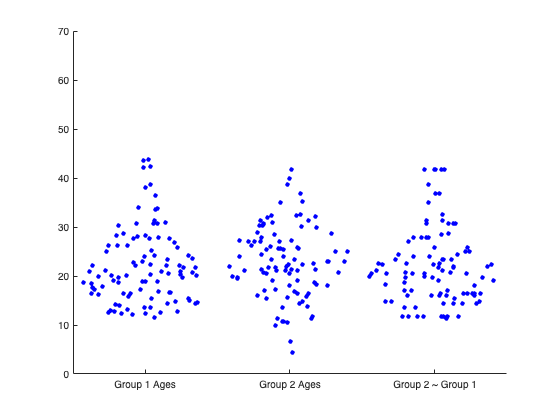

%Both groups have shared means and standard deciations
group_mean = 23.5;
group_std = 8;

%Group one can have a skew
g1_skew = 0.71;

%Set the size of each group
N_g1 = 100;
N_g2 = 100;

%Set the number of samples to take
N_samples = 100;

%Set group 1 to be a skewed distribution
g1_ages = pearsrnd(group_mean,group_std,g1_skew,3,N_g1,1)';

%Set group 2 to be normally distributed
g2_ages = randn(1,N_g2)*group_std + group_mean;

method = "closest";

if strcmpi(method,'weighted')
    % Perform kernel density estimation
    [f, xi] = ksdensity(g1_ages);

    % Evaluate the estimated density at the new value
    weights = max(interp1(xi, f, g2_ages),1e-10); %Keep values positive

    g2_samp_ages = g2_ages(randsample(N_g2,N_samples,true,weights)');

else
    %We can add noise to the sampled ages to make sure we get some variations
    %in subjects picked, rather than just the closest one
    age_jitter = 0;

    %Sample with replacement from group 1 to get a set of ages (plus optional
    %jitter)
    g1_samp_inds = randi(N_g1,1,N_samples);
    g1_samp_ages = g1_ages(g1_samp_inds)+randn(1,N_samples)*age_jitter;

    %For each sampled age from group 1, get the closest age from group 2
    g2_samp_ages = findclosest(g2_ages, g1_samp_ages);
end

%Create the plot values
x = [ones(1,N_g1), ones(1,N_g2)*2, ones(1,N_samples)*3];
y = [g1_ages, g2_ages, g2_samp_ages];

swarmchart(x,y,20,"blue","filled")
set(gca,'xtick',1:3,'XTickLabel',{'Group 1 Ages', 'Group 2 Ages', 'Group 2 ~ Group 1'})
ylim([0 70])


%Check to see that we are drawing from the correct distribution
assert(all(ismember(g2_samp_ages,g2_ages)));



